## Create historical data

dose_streaks = ...
[
    9;
    8;
    7;
    6;
    5;
    4
];

elapsed_days = sum( dose_streaks ) + length( dose_streaks );
start_datetime = datetime( '29-Mar-2026' ) - elapsed_days;

dose_history = ones( elapsed_days, 1 );
d = 0;
for i = 1 : length( dose_streaks )
    s = dose_streaks( i );
    d = d + s + 1;
    dose_history( d ) = 0;
end

## Append hisotory daily

dose_history( end + 1 ) = 1; % Mon-30-Mar-2026
dose_history( end + 1 ) = 1; % Tue-31-Mar-2026
dose_history( end + 1 ) = 1; % Wed-01-Apr-2026
dose_history( end + 1 ) = 0; % Thu-02-Apr-2026
dose_history( end + 1 ) = 1; % Fri-03-Apr-2026
dose_history( end + 1 ) = 1; % Sat-04-Apr-2026
dose_history( end + 1 ) = 1; % SUn-05-Apr-2026
dose_history( end + 1 ) = 0; % Mon-06-Apr-2026
dose_history( end + 1 ) = 1; % Tue-07-Apr-2026
dose_history( end + 1 ) = 1; % Wed-08-Apr-2026
dose_history( end + 1 ) = 0; % Thu-09-Apr-2026
dose_history( end + 1 ) = 1; % Fri-10-Apr-2026
dose_history( end + 1 ) = 1; % Sat-11-Apr-2026
dose_history( end + 1 ) = 0; % Sun-12-Apr-2026
dose_history( end + 1 ) = 1; % Mon-13-Apr-2026
dose_history( end + 1 ) = 1; % Tue-14-Apr-2026
dose_history( end + 1 ) = 0; % Wed-15-Apr-2026
dose_history( end + 1 ) = 0; % Thu-16-Apr-2026
dose_history( end + 1 ) = 1; % Fri-17-Apr-2026
dose_history( end + 1 ) = 1; % Sat-18-Apr-2026


## Analyse

exp_dedose = @( day ) exp( - day / 150 );
lin_dedose = @( day ) 1 - day / 180;
mean_dose_history = movmean( dose_history, 10 );
cum_dose_history  = cumsum( dose_history );

## Visualise

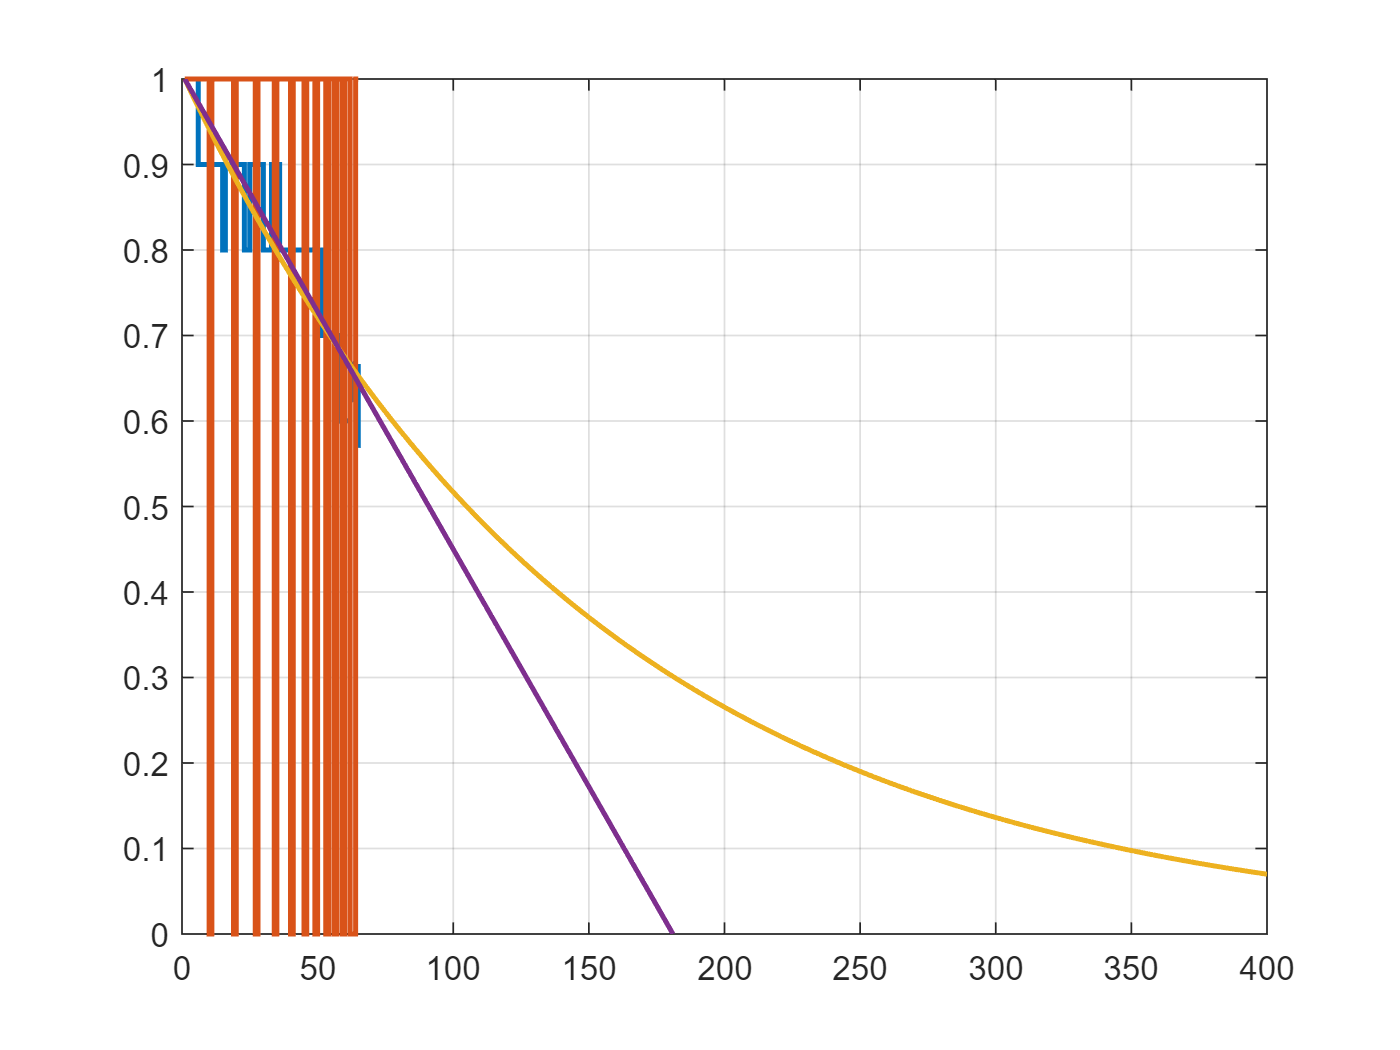

figure
stairs( mean_dose_history, 'LineWidth', 1.5 );
hold on;
stairs( dose_history, 'LineWidth', 1.5 );
plot( exp_dedose( 0:399 ), 'LineWidth', 1.5 );
plot( lin_dedose( 0:180), 'LineWidth', 1.5 );
hold off;
grid on;

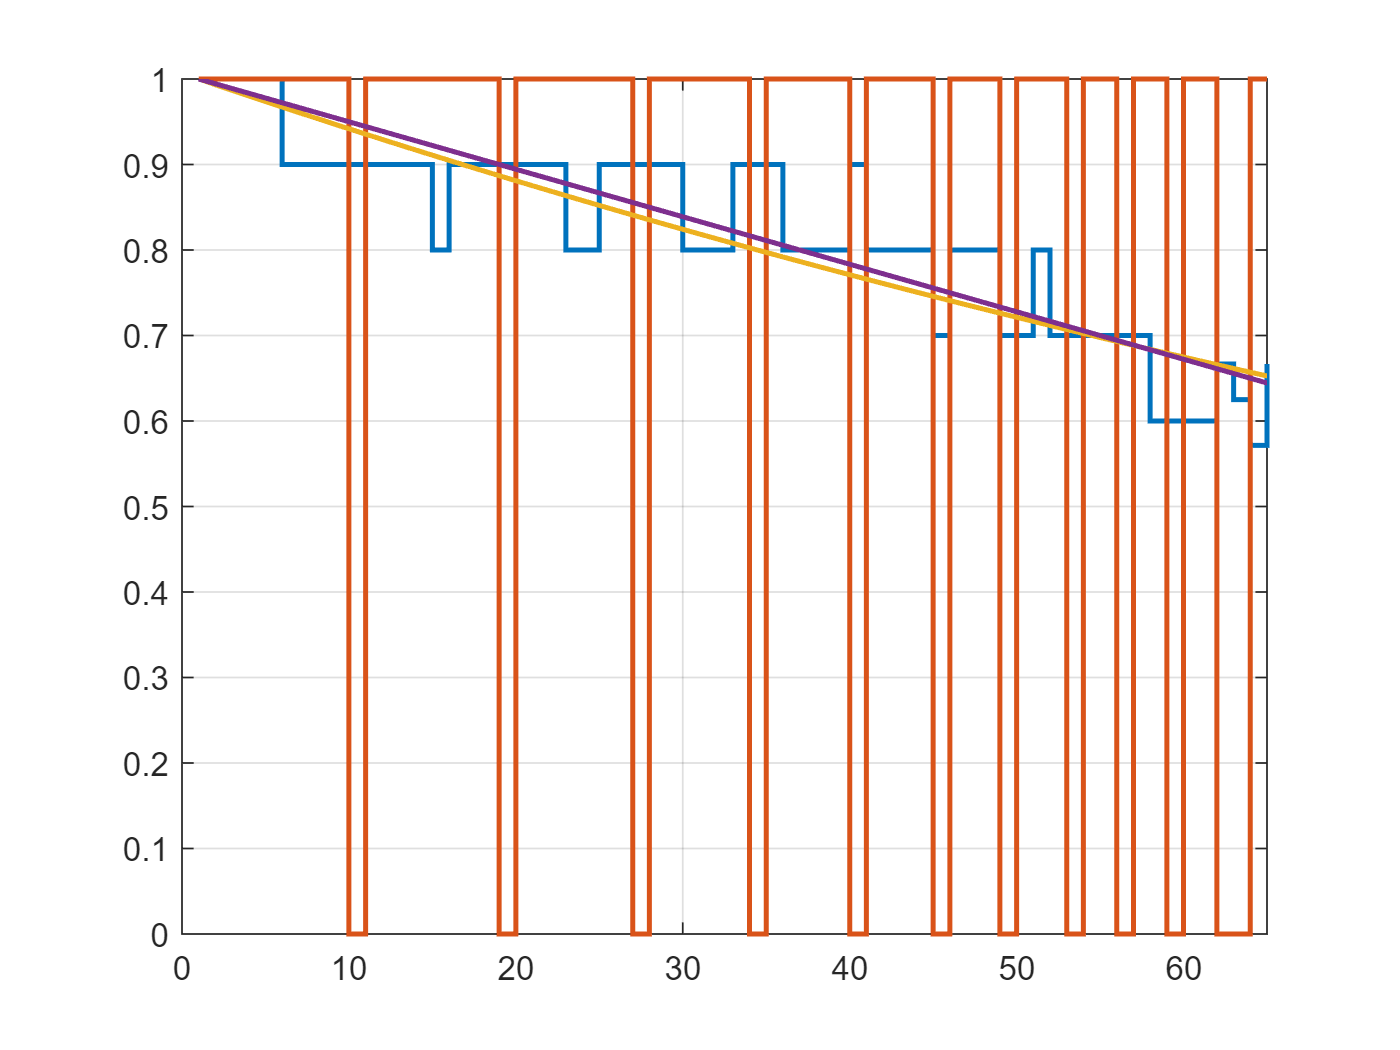


figure
stairs( mean_dose_history, 'LineWidth', 1.5 );
hold on;
stairs( dose_history, 'LineWidth', 1.5 );
plot( exp_dedose( 0:399 ), 'LineWidth', 1.5 );
plot( lin_dedose( 0:180), 'LineWidth', 1.5 );
hold off;
grid on;
xlim( [ 0, length( dose_history ) ] );

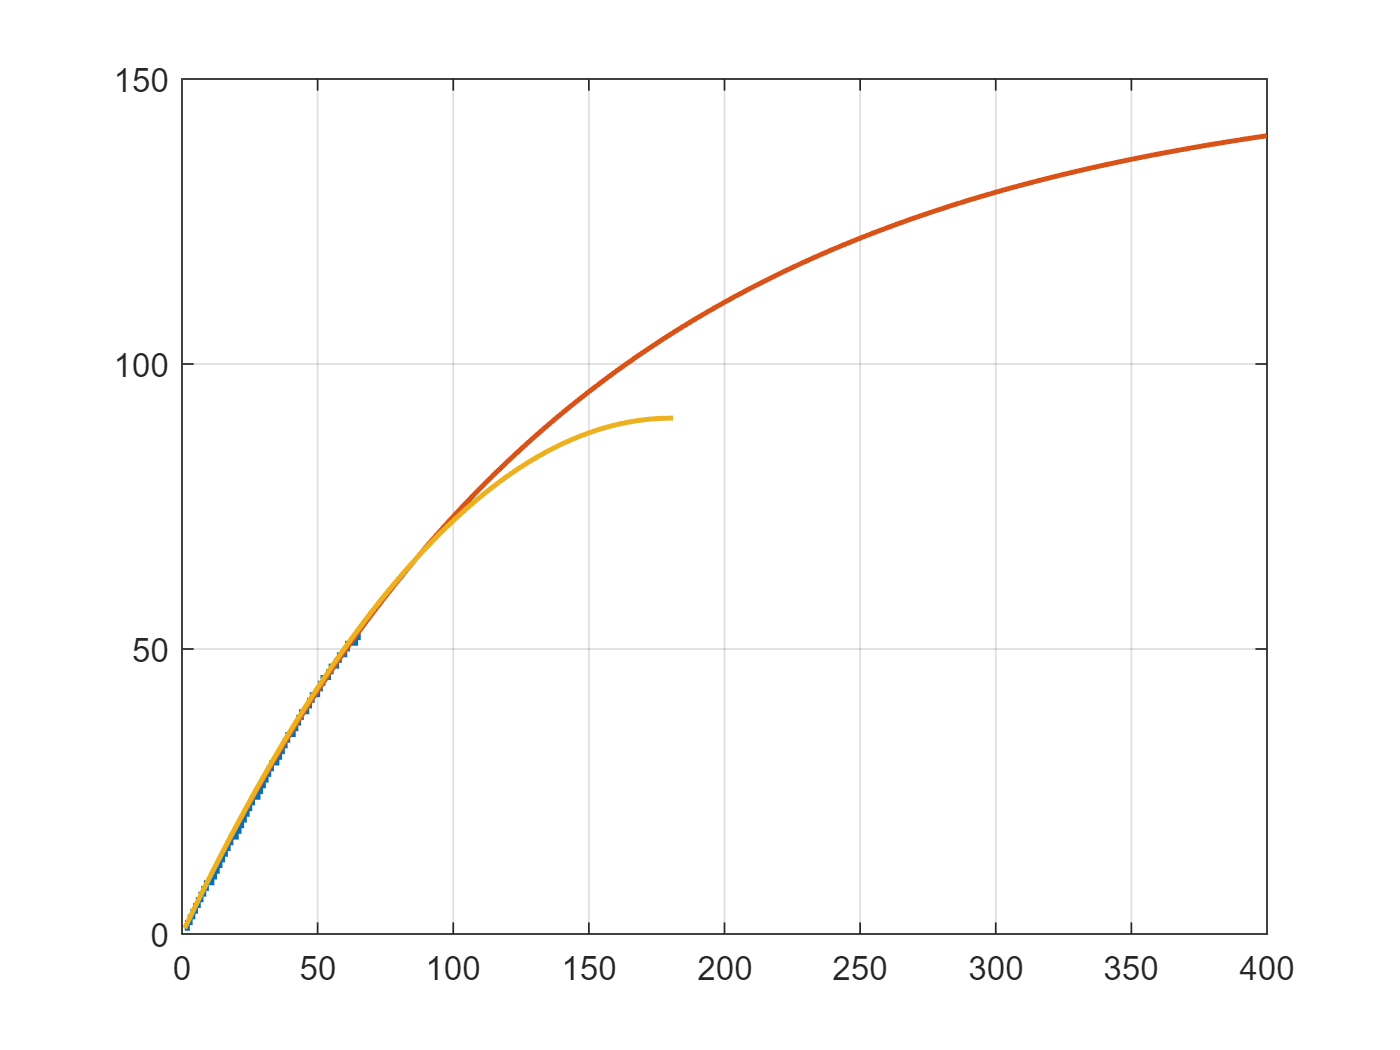

figure
stairs( cum_dose_history, 'LineWidth', 1.5 );
hold on;
plot( cumsum( exp_dedose(0:399) ), 'LineWidth', 1.5 );
plot( cumsum( lin_dedose(0:180) ), 'LineWidth', 1.5 );
hold off;
grid on;

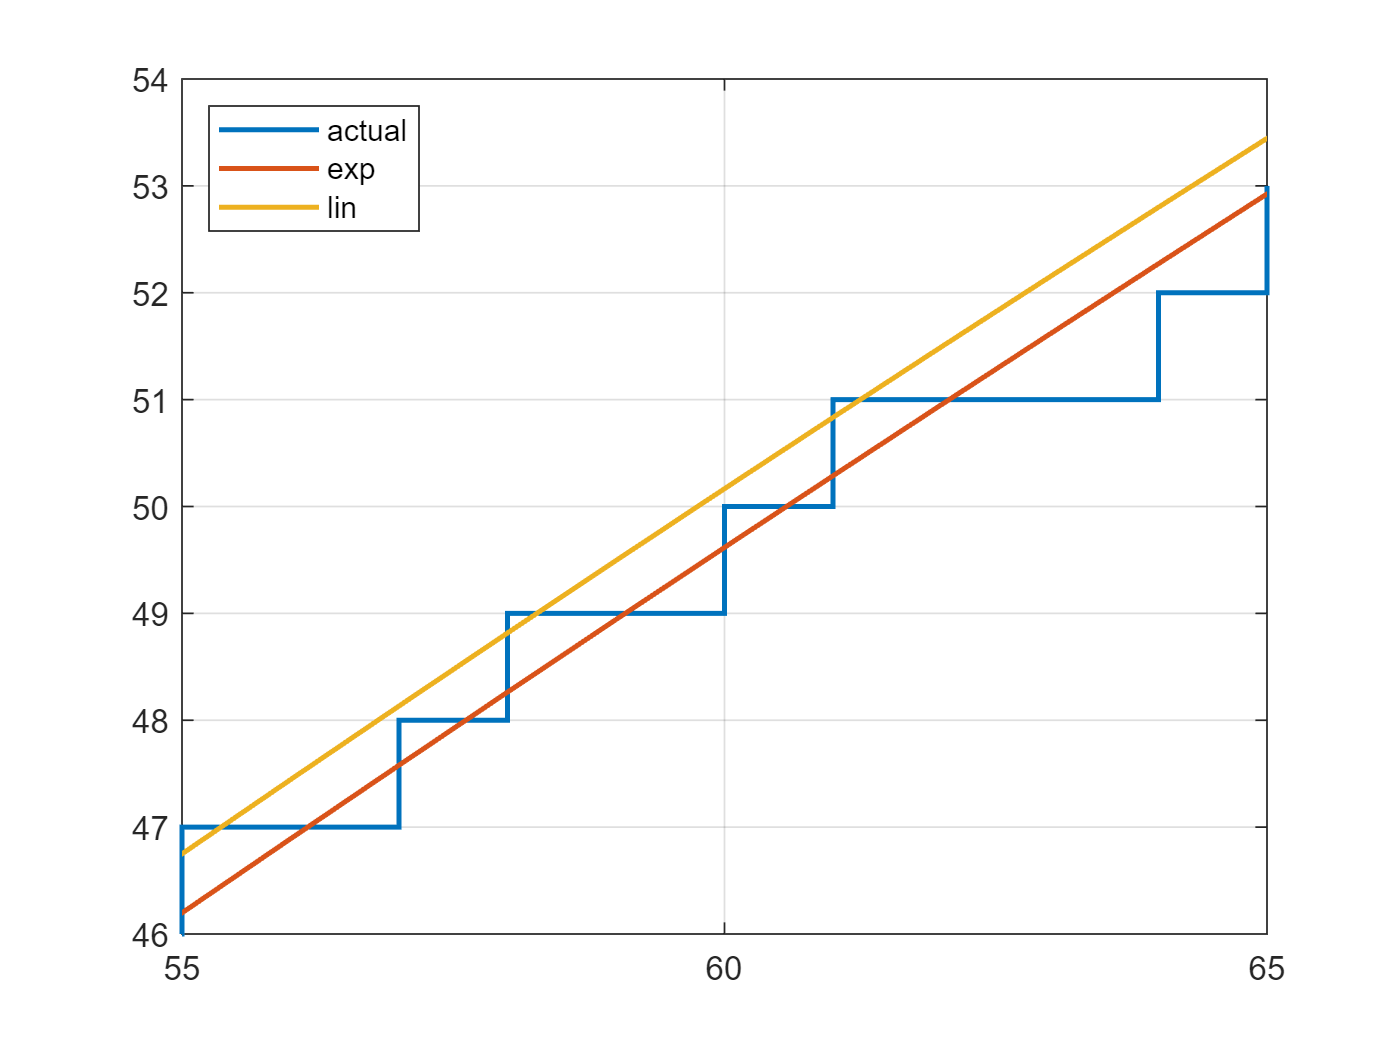

figure
stairs( cum_dose_history, 'LineWidth', 1.5 );
hold on;
plot( cumsum( exp_dedose(0:399) ), 'LineWidth', 1.5 );
plot( cumsum( lin_dedose(0:180) ), 'LineWidth', 1.5 );
hold off;
grid on;
xlim( [ length( dose_history ) - 10, length( dose_history ) ] );
legend( 'actual', 'exp', 'lin', 'Location', 'northwest' );